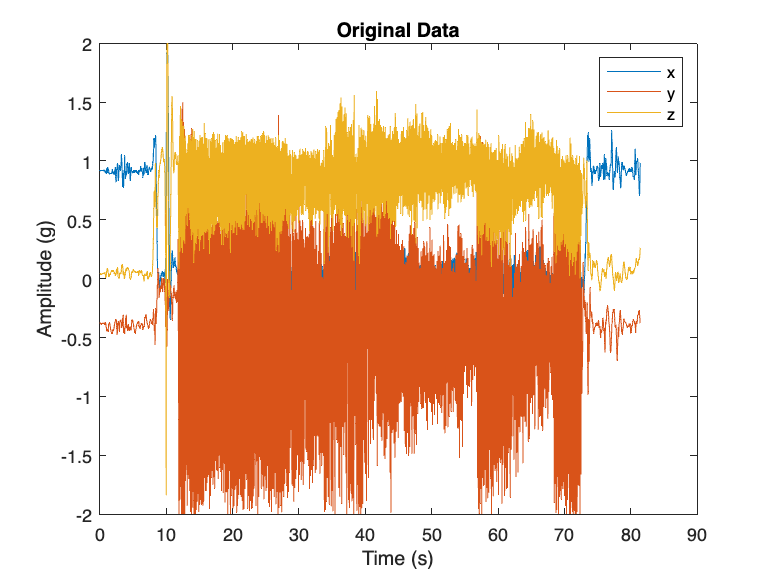

m = readmatrix("data/distance.csv","Range",'C:F');
t = m(2:length(m),1); % time (s)
x = m(2:length(m),2); % x-axis data (g)
y = m(2:length(m),3); % y-axis data (g)
z = m(2:length(m),4); % z-axis data (g)

freq  = 50; % frequency (Hz)

figure;
plot(t,x);
hold on
plot(t,y);
plot(t,z);
legend(["x" "y" "z"]);
xlabel("Time (s)");
ylabel("Amplitude (g)");
title("Original Data");

## PSD

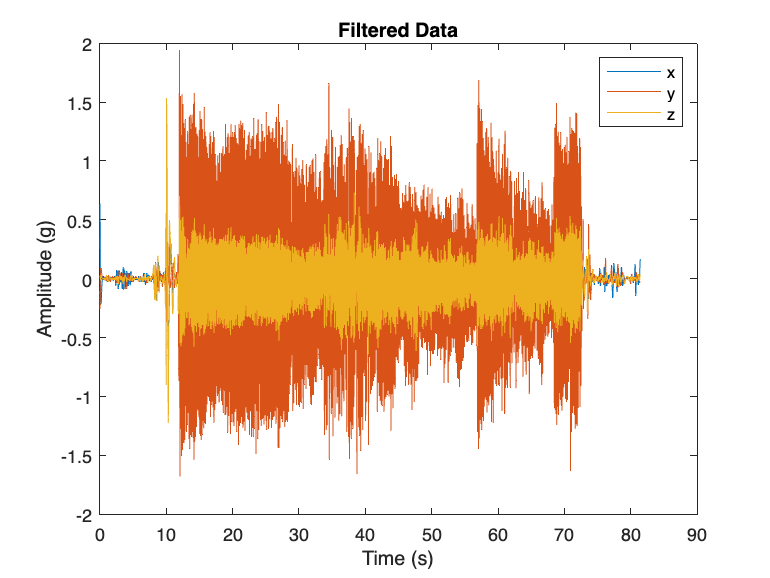

% insert the start time for tremor (edit as needed)
start = find(t == 11.915); % start point for tremor
stop = start+3000; % stop point for tremorfps

% design butterworth bandpass filter
low_cut = 2; % lower cut off frequency (Hz)
high_cut = 14; % higher cut off frequency (Hz)
[b, a] = butter(2, [low_cut/(freq/2) high_cut/(freq/2)],'bandpass');

x = filter(b,a,x);
y = filter(b,a,y);
z = filter(b,a,z);

figure;
plot(t,x);
hold on
plot(t,y);
plot(t,z);
legend(["x" "y" "z"]);
xlabel("Time (s)");
ylabel("Amplitude (g)");
title("Filtered Data")

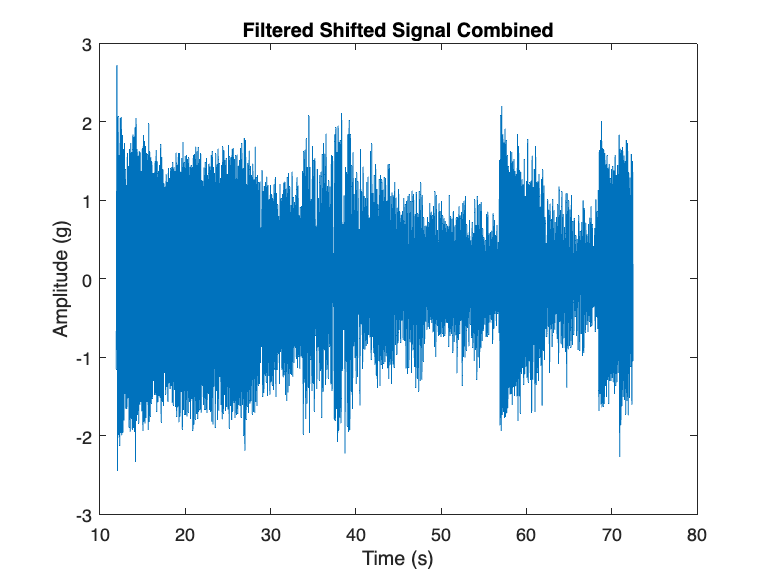


signal_comb = x(start:stop)+y(start:stop)+z(start:stop);
figure;
plot(t(start:stop),signal_comb);
xlabel("Time (s)");
ylabel("Amplitude (g)");
title("Filtered Shifted Signal Combined")

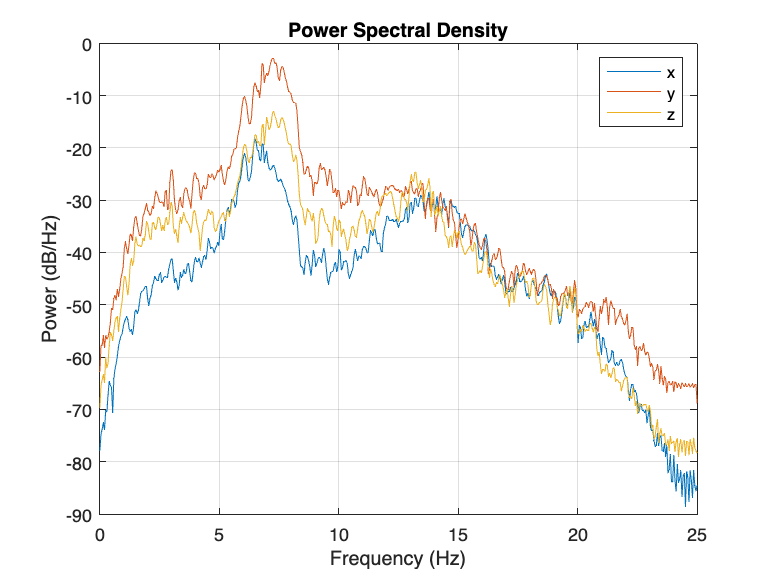


% save combined signal for coherence test with other signals
fileName = "distance_signal.mat";
save(fileName,"signal_comb");

[psd_x,f] = pwelch(x(start:stop),[],[],[],freq);
[psd_y,f] = pwelch(y(start:stop),[],[],[],freq);
[psd_z,f] = pwelch(z(start:stop),[],[],[],freq);

% combined x,y,z axis amplitudes
[psd_combined,f] = pwelch(signal_comb,[],[],[],freq);

figure;
pwelch(x(start:stop),[],[],[],freq);  % Plot in decibels (dB)
hold on
pwelch(y(start:stop),[],[],[],freq); 
pwelch(z(start:stop),[],[],[],freq); 
legend(["x" "y" "z"]);

xlabel('Frequency (Hz)');
ylabel('Power (dB/Hz)');
title('Power Spectral Density');
hold off

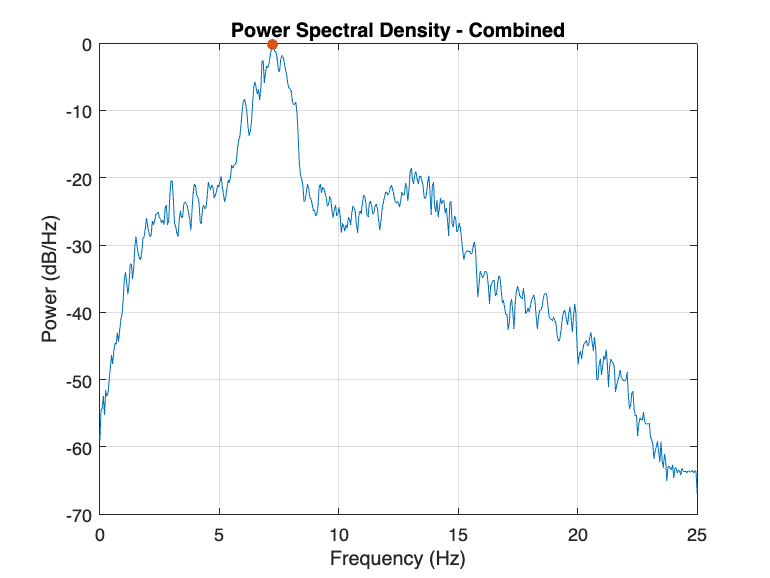


figure;
pwelch(x(start:stop)+y(start:stop)+z(start:stop),[],[],[],freq);
hold on

[maxValue, maxIndex] = max(psd_combined); % plot max value
amplitude = 10*log10(maxValue); % amplitude of dominant tremor frequency

scatter(f(maxIndex),amplitude,'filled');

xlabel('Frequency (Hz)');
ylabel('Power (dB/Hz)');
title('Power Spectral Density - Combined');
hold off

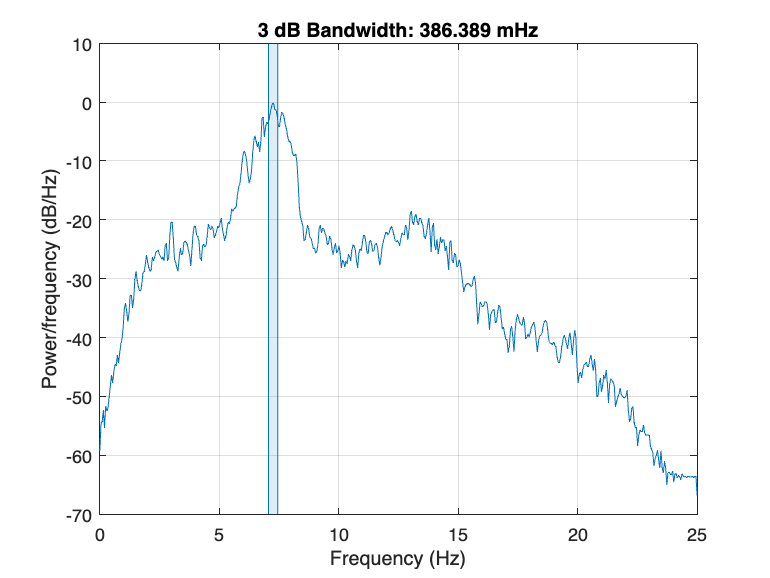


% Calculate 3-dB (half power) bandwidth 
[bandwidth,freq_lower,freq_higher,band_power] = powerbw(psd_combined,f);
figure; 
powerbw(psd_combined,f);

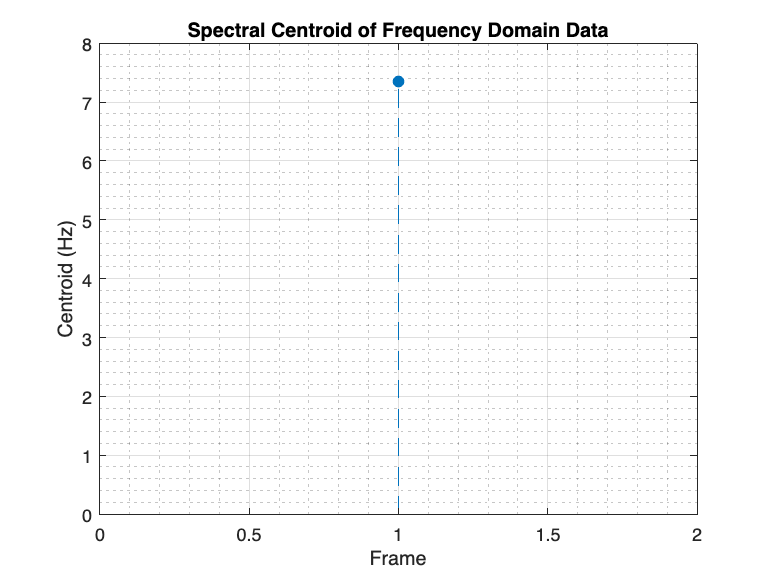


% Calculate spectral centroid
spectral_centroid = spectralCentroid(psd_combined,f);
figure;
spectralCentroid(psd_combined,f);
title("Spectral Centroid of Frequency Domain Data")

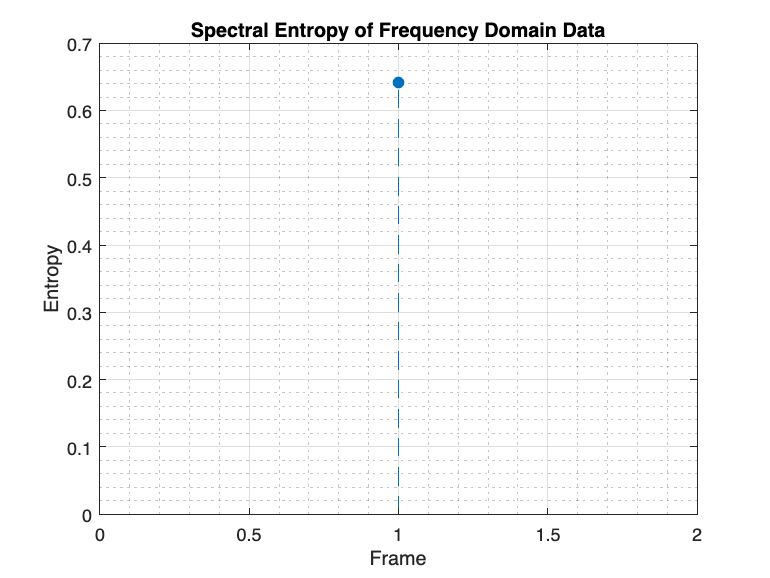


% Calculate spectral entropy
spectral_entropy = spectralEntropy(psd_combined,f);
figure;
spectralEntropy(psd_combined,f);
title("Spectral Entropy of Frequency Domain Data")


disp(['Dominant Frequency: ',num2str(f(maxIndex)), ' Hz'])

Dominant Frequency: 7.2266 Hz


disp(['Amplitude: ',num2str(amplitude), ' dB/Hz'])

Amplitude: -0.2377 dB/Hz


disp(['Bandwidth: ',num2str(bandwidth), ' Hz'])

Bandwidth: 0.38639 Hz


disp(['Lower Bound: ',num2str(freq_lower), ' Hz'])

Lower Bound: 7.0636 Hz


disp(['Upper Bound: ',num2str(freq_higher), ' Hz'])

Upper Bound: 7.45 Hz


disp(['Percent Power Stored in Bandwidth: ',num2str(band_power), ' dB']);

Percent Power Stored in Bandwidth: 0.28644 dB


disp(['Spectral Centroid: ',num2str(spectral_centroid), ' Hz']);

Spectral Centroid: 7.3447 Hz


disp(['Spectral Entropy: ',num2str(spectral_entropy)]);

Spectral Entropy: 0.64181
